% Sistema de Vector de colores
matriz = [0 60; 1 58; 2 56; 3 54; 4 52; 5 50; 6 48; 7 46; 8 44; 9 42; 10 40];

% Matriz combinada con los datos obtenidos
%matriz_combinada = cat(2,tiempo_v.',intensity_v.');
%matriz_combinada_invertida = cat(2,tiempo_v.',flip(intensity_v).');

% Se depura la data quedándose sólo con los datos de los colores analizados
matriz_depurada = depura_matrices(matriz_combinada, 100, 390)

matriz_depurada = 5779×2 int32 matrix
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60


matriz_depurada2 = depura_matrices(matriz_combinada2, 100, 409)

matriz_depurada2 = 6159×2 int32 matrix
   101    58
   101    58
   101    58
   101    58
   101    58
   101    58
   101    58
   101    58
   101    58
   101    58


matriz_depurada3 = depura_matrices(matriz_combinada3, 100, 425)

matriz_depurada3 = 6479×2 int32 matrix
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60


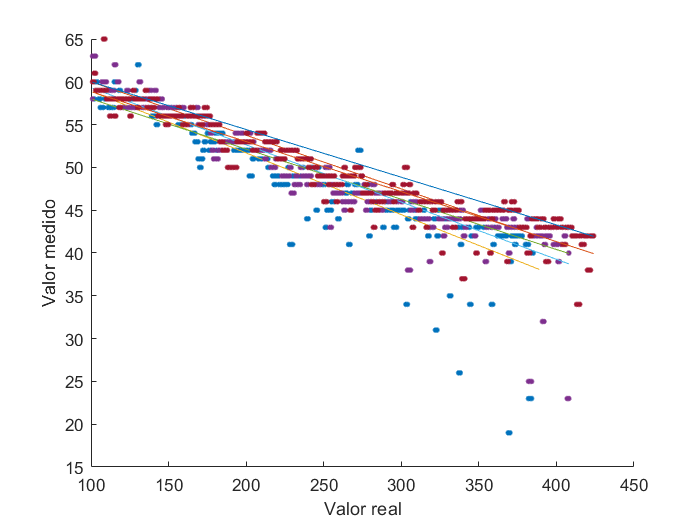

%matriz_depurada4 = depura_matrices(matriz_combinada_invertida, 56, 320);

% Curva de Calibración

hold on
TestRecta(matriz_depurada(:,1).',matriz_depurada(:,2).', 100)
TestRecta(matriz_depurada2(:,1).',matriz_depurada2(:,2).', 100)
TestRecta(matriz_depurada3(:,1).',matriz_depurada3(:,2).', 100)
hold off

%TestRecta(matriz_depurada4(:,1).',matriz_depurada4(:,2).', 56)



function matriz_limpia = depura_matrices(matriz, corte_inicio, corte_final)    
    matriz_limpia = [];
    for i = 1: size(matriz,1)
        if matriz(i,1) > corte_inicio && matriz(i,1) < corte_final
            matriz_limpia = [matriz_limpia; matriz(i,:)];
        end
    end
end
